folder_where_RFTtoolbox_is_saved = 'C:/Users/qyc71/Documents/2022-2023 courses/Rotation winter/RFTtoolbox';
addpath(genpath(folder_where_RFTtoolbox_is_saved))

1D convolution fields

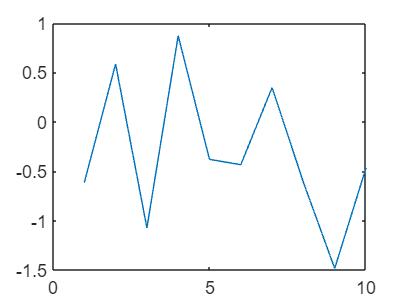

ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10]
              YData: [-0.6147 0.5848 -1.0739 0.8707 -0.3799 -0.4342 0.3467 -0.6124 -1.4840 -0.4664]

  Show all properties


clf; nvox = 10; resadd = 10; xvals = 1:nvox;
FWHM = 1.5; lat_data = wfield([nvox,1]); % a white Gaussian field
plot(lat_data)

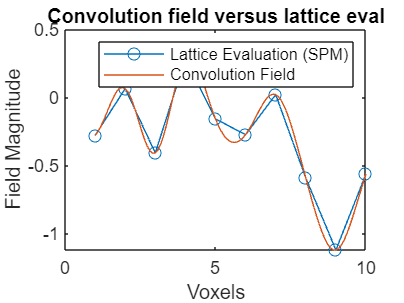

lattice_field = fconv(lat_data.field, FWHM); % default is Gaussian kernal?
params = ConvFieldParams(FWHM, resadd, 0); % ? as above
cfield = convfield( lat_data, params );
% what parameters are needed for a field and a kernal?
% plots
plot(xvals, lattice_field, 'o-')
hold on
plot(cfield);
title('Convolution field versus lattice eval')
xlabel('Voxels'); ylabel('Field Magnitude')
legend('Lattice Evaluation (SPM)', 'Convolution Field')

% local maxima (x and y)
max_x_vec = [];
max_y_vec = [];
max_x = cfield.xvals{1}(lmindices(cfield.field));
if max_x ~= 1 && max_x ~= 10
    max_x_vec = [max_x_vec, max_x];
    max_y_vec = [max_y_vec, cfield.field(lmindices(cfield.field))];
end

% all peaks
cfield.xvals{1}(lmindices(cfield.field, 'all'));
cfield.field(lmindices(cfield.field, 'all'));
% top 2
cfield.xvals{1}(lmindices(cfield.field, 2));
cfield.field(lmindices(cfield.field, 2));

Simulations, exlude points on the boundry

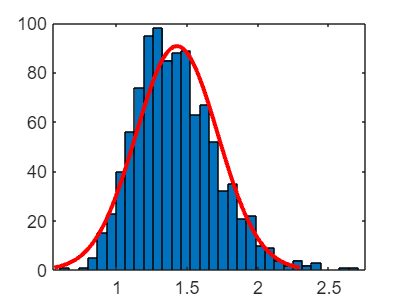

clf; M = 1000; 
nvox = 100; resadd = 10; xvals = 1:nvox;
FWHM = 2;
max_x_vec = [];
max_y_vec = [];
for i = 1:M
    lat_data = wfield([nvox,1]);
    params = ConvFieldParams(FWHM, resadd, 0);
    cfield = convfield( lat_data, params);
    max_x = cfield.xvals{1}(lmindices(cfield.field));
    if max_x ~= 1 && max_x ~= nvox
        max_x_vec = [max_x_vec, max_x];
        max_y_vec = [max_y_vec, cfield.field(lmindices(cfield.field))];
    end
end


%histfit(max_y_vec)

Peak (nvox=1000, FWHM = ..., decrease M maybe)

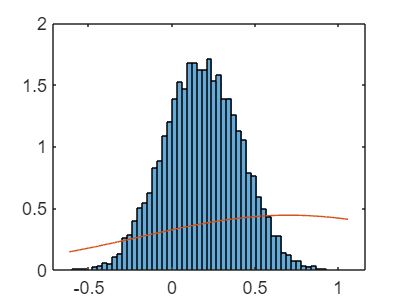

clf; M = 100; 
nvox = 1000; resadd = 10; xvals = 1:nvox;
FWHM = 4;
max_x_vec = [];
max_y_vec = [];
for i = 1:M
    lat_data = wfield([nvox,1]);
    params = ConvFieldParams(FWHM, resadd, 0);
    [cfield, ss] = convfield(lat_data, params);
    cfield.field = cfield.field/sqrt(ss);
    max_x = cfield.xvals{1}(lmindices(cfield.field,'all'));
    max_y = transpose(cfield.field(lmindices(cfield.field, 'all')));
    if ismember(1,max_x)
        max_x = max_x(2:length(max_x));
        max_y = max_y(2:length(max_y));
    end
    if ismember(nvox,max_x)
        max_x = max_x(1:(length(max_x)-1));
        max_y = max_y(1:(length(max_y)-1));
    end
    max_x_vec = [max_x_vec, max_x];
    max_y_vec = [max_y_vec, max_y];
end
% N=1, k=1, theoretical density
% correct?
k = 1;
x = (0:1000)/1000*range(max_y_vec) + min(max_y_vec);
thm_density = sqrt(3-k^2)/sqrt(6*pi)*exp(-3*x.^2/(2*(3-k^2)))...
    + 2*k*x*sqrt(pi)/sqrt(6).*normpdf(x)...
    .*normcdf(k*x/sqrt(3-k^2));

% how to plot density over histogram?
histogram(max_y_vec, 'Normalization','pdf')
hold on
plot(x, thm_density)

% integral(thm_density, -2, 4)

2d

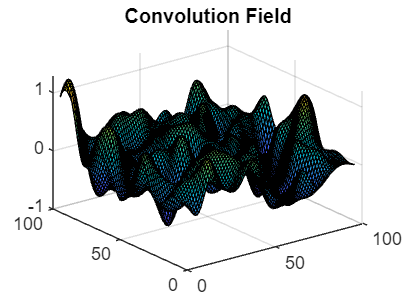

clf;Dim = [20,20]; D = length(Dim); resadd = 4; FWHM = 2;
lat_data = wfield(Dim);
params = ConvFieldParams([FWHM,FWHM], resadd, 0);
fine_data = convfield( lat_data, params);
surf(fine_data.field)
title('Convolution Field')

Simulation

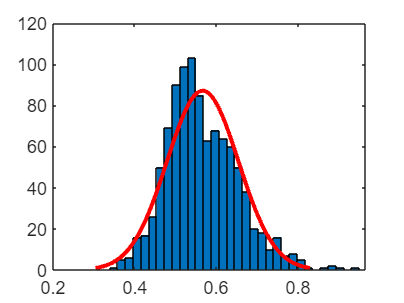

clf; M = 1000; 
Dim = [20,20]; D = length(Dim); resadd = 4; FWHM = 2;
lat_data = wfield(Dim);
params = ConvFieldParams([FWHM,FWHM], resadd, 0);
max_x_mat = [];
max_y_vec = [];
for i = 1:M
    lat_data = wfield(Dim);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    max_x = fine_data.xvals{1}(lmindices(fine_data.field));
    max_x_mat = [max_x_mat; max_x];
    temp = lmindices(fine_data.field);
    max_y_vec = [max_y_vec; fine_data.field(temp(1), temp(2))];
end
%histfit(max_y_vec)

Peak

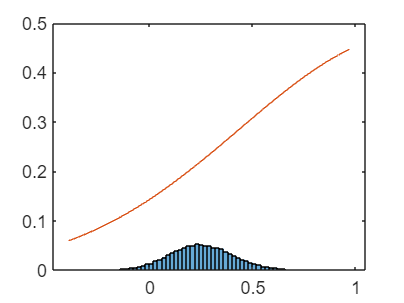

clf; M = 1000; 
Dim = [20,20]; D = length(Dim); resadd = 4; FWHM = 2;
lat_data = wfield(Dim);
params = ConvFieldParams([FWHM,FWHM], resadd, 0);
max_x_mat = [];
max_y_vec = [];
for i = 1:M
    lat_data = wfield(Dim);
    [fine_data, ss] = convfield(lat_data, params);
    fine_data.field = fine_data.field/sqrt(ss);
    max_x = fine_data.xvals{1}(lmindices(fine_data.field, 'all'));
    max_x_mat = [max_x_mat, max_x];
    temp = lmindices(fine_data.field, 'all');
    size_temp = size(temp);
    for j = 1:size_temp(2)
        if temp(1,j) ~= length(fine_data.field) &&...
               temp(2,j) ~= length(fine_data.field) &&...
               temp(1,j) ~= 1 && temp(2,j) ~= 1
            max_y_vec = [max_y_vec;...
            fine_data.field(temp(1, j), temp(2, j))];
        end
        
    end
end

k = 1;
x = (0:1000)/1000*range(max_y_vec) + min(max_y_vec);
thm_density = sqrt(3)*k^2*(x.^2-1).*normpdf(x)...
    .*normcdf(k*x/sqrt(2-k^2)) + k*x*sqrt(3*(2-k^2))/(2*pi).*...
    exp(-x.^2/(2-k^2)) + sqrt(6)/sqrt(pi*(3-k^2))...
    *exp(-3*x.^2/(2*(3-k^2)))...
    .*normcdf(k*x/sqrt(3-k^2)/sqrt(2-k^2));

histogram(max_y_vec, 'Normalization', 'probability')
hold on
plot(x, thm_density)